## How to get contents of a script/function: 

- Go to its directory and say:

- type scriptname

**How to Get Block Comment of a Script:  %%%%**

- help scriptname

**How to Make a Comment Block: **%{ texthere over many lines %}

**Input Function (WARNING: use single quotes, not double)**

% note: keeps prompting until numeric is entered
% error if 23q is entered, char passes
radius = input('Enter the radius: ')

radius =      5


% If you want a char/string input
aChar = input('Enter a character: ', 's')

aChar = 'blankafter    '

length(aChar)

ans =     14


% can also use single quotes in input, without 's'
% in input function, to call the char function input
name = input('Enter your name: ') 

name = 'Diana'

length(name)

ans =      5


eleven = 11; 
num = input('Enter a number: ')

num =     11


**Entering a vector:**

v = input('Enter a vector: ')

v =      1     2     3


**OUTPUT STATEMENTS: disp, fprintf**

% Next prompt  always appears on next line, no need
% for newline char. 
disp('He...llo...')

He...llo...


disp(4^3)

    64



% allows formatting, while disp doesn't

% NOTE: IN COMMAND LINE WINDOW, if you don't place
% a newline char at the end (\n) then the next prompt
% appears on same ending line as fprintf's. 
fprintf('The value is %d, surely!', 4^3)

The value is 64, surely!

disp('hi')

hi


%d - integer (stands for decimal integer)

%f = float

%c = character (one only)

%s = string of chars

fprintf(['The value is %d, \n' ...
    'OK?\n' ...
    'And the next line is here.'], 4^3)

The value is 64, 
OK?
And the next line is here.

Newline is the ONLY formatting character allowed in input() function

x = input('Enter the \n x-coordinate: ')

x =     23


y = input(' y-coordinate: ')

y =      1


fprintf('The int is %d and the char is %c\n', 33-2, 'x')

The int is 31 and the char is x


**Field Widths for fprintf(): **

Field width of %n.mf for floats means: 

n = total width (including the decimal point . and (m))

m = num decimal points

fprintf('The int is %3d and the float is %6.2f\n',5, 4.9)

The int is   5 and the float is   4.90



fprintf(['This means 3 decimals %.3f, regardless of' ...
    'the field width'], 123.2348)

This means 3 decimals 123.235, regardless ofthe field width


% note: if field width is bigger than necessary,
% leading BLANKS are printed, and if decimals is
% bigger than necessary, trailling zeroes are printed.
fprintf('testing xx%10.4fxx ', 12.89)

testing xx   12.8900xx 

**Left and right Justification**

- left justify is: %-5d

- natural right justify is: %5d

fprintf(['\nthe float is xx%10.3fxx and\n' ...
    'the integers are \n' ...
    '__%-5d__ and\n' ...
    '__%5d__\n'], 3.1, 3, 3)


the float is xx     3.100xx and
the integers are 
__3    __ and
__    3__


% string truncation: 
fprintf('%s', 'street')

street

fprintf('%.2s', 'street')

st

fprintf('%3.2f\n', 1234.5678)

1234.57



% result: scientific notation, when using integer
% conversion character to print REAL number
fprintf('%d\n', 12347.89) % not correct way to get sci

1.234789e+04


**Other Formatting**

% Slashes
fprintf('this is tab:\tanimal')

this is tab:	animal

fprintf('this is ''quote'' ')

this is 'quote' 

fprintf('this is slash \\ okie \\ dokie? /\n')

this is slash \ okie \ dokie? /


**Printing Vectors**

% printing in column format - must use newline
vec = 2:5;
fprintf('%d\n', vec)

2
3
4
5



% printing in row format - must not use newline
fprintf('%d', vec)

2345


% spaces
%$$$
fprintf('%d', vec)

2345

fprintf('\n')

**Printing Matrices**

% by unwinding
mat = [5 9 8; 4 1 10]

mat =      5     9     8
     4     1    10


fprintf('%d\n', mat)

5
4
9
1
8
10


% by column (but still unwound, just in col format)
fprintf('%d %d %d\n', mat)

5 4 9
1 8 10


% by column - correct way (must use transpose)
fprintf('%d %d %d\n', mat')

5 9 8
4 1 10


**DISP is easier to use than FPRINTF for vecs and matrices: **

mat = [15 11 14; 7 10 13]

mat =     15    11    14
     7    10    13


disp(mat)

    15    11    14
     7    10    13




vec = 2:5

vec =      2     3     4     5


disp(vec)

     2     3     4     5



**PLOTTING**

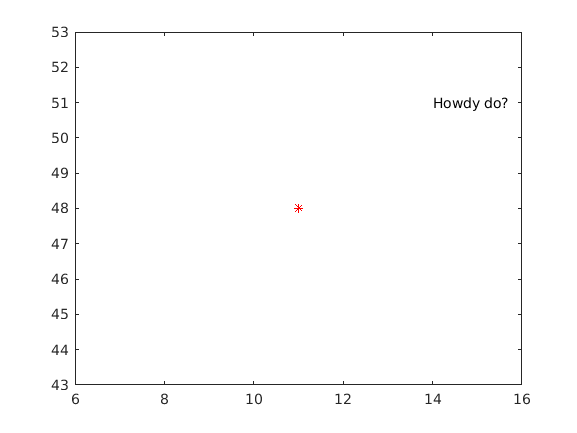

Area: 



area =

     []



Undefined function or variable 'tempscript'.

% Plotting one red point

clf
% create coordinates and plot a red '*'
x = 11; y = 48; 
plot(x, y, 'r*')
axis([x-5, x+5, y-5, y+5])
text(x+3, y+3, 'Howdy do?')

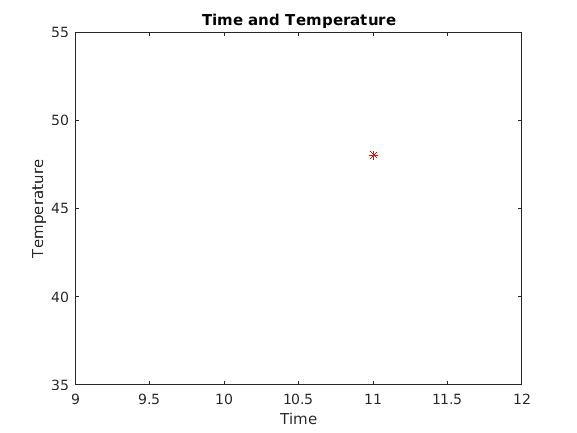


% change axes and label them
axis([9 12, 35 55])
xlabel('Time')
ylabel('Temperature')

% put a title on the plot
title('Time and Temperature')

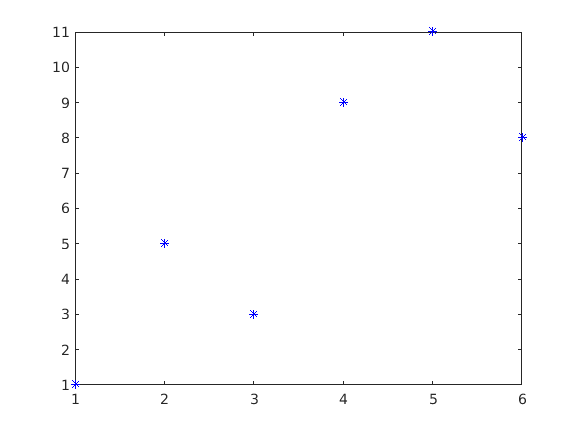

% Plotting many points
x = 1:6; 
y = [1 5 3 9 11 8];
plot(x, y, 'b*')

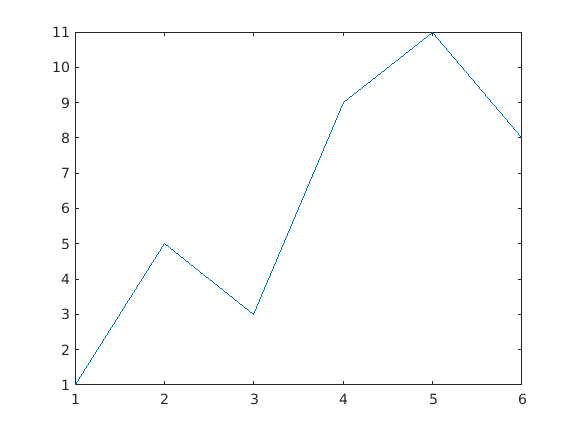

plot(x, y)

plot(y) % works since xs are indices of ys

% how to get the ranges used in axes: 
axis

ans =      1     6     1    11


**Possible Plot Colors: **

b - blue

g = green

r = red

c = cyan

m = magenta

y = yellow

k = black

w = white

**Possible Plot Symbols / Markers: **

. = point

o = circle

x = x-mark

+ = plus

* = star

s = square

d = diamond

v = down triangle

^ = up triangle

< = left triangle

> = right triangle

p = pentagram

h = hexagram

**Line Types:**

- solid

: dotted

-. dashdot

-- dashed

(none) no line

IF NOTE LINE TYPE and NO MARKER, then solid line is drawn between points.

**COMMANDS**

clf = clears Figure Window

figure = creates new empty Figure Window

figure(n) = makes multiple figure windows, and allows you to refer to each individually.

hold = freezes current graph in Figure Window so new ones can be superimposed on current one (hold on, hold off)

legend: displays strings

grid = displays grid lines on graph (grid on, grid off)

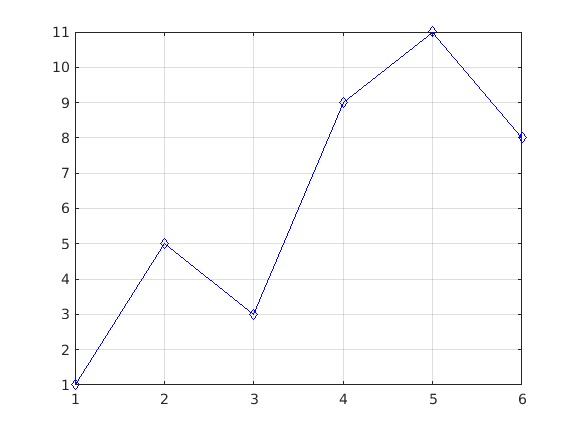

grid on
hold on
plot(x,y, 'b-d')

**Bar Chart**

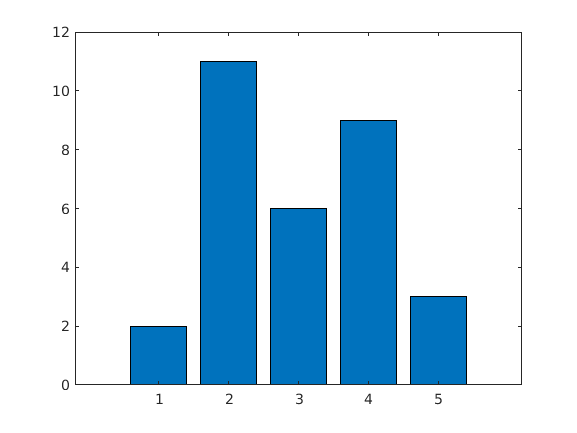

% Creating 2 different plots in 2 different Figure
% Windows. 

clf
x = 1:5; %not necessary
y1 = [2 11 6 9 3];
y2 = [4 5 8 6 2];

% Put bar chart in figure 1
figure(1)
bar(x, y1)

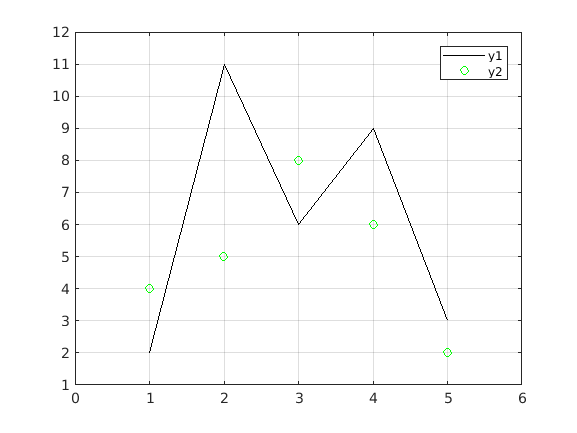


% Put plots using different y-values on one plot 
% with legend
plot(x, y1, 'k')
hold on
plot(x, y2, 'go')
grid on
legend('y1', 'y2')
axis([0 6, 1 12])

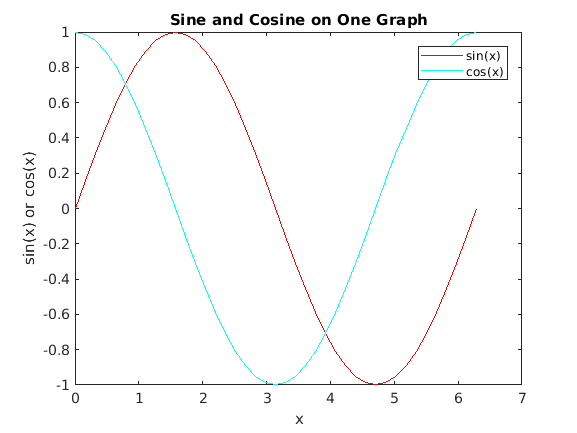

% Plotting sin and cosine in the same Figure Window
clf
x = 0: 2*pi/40: 2*pi; 
y = sin(x);
plot(x, y, 'r-') %, x, y, 'ro')

hold on
y = cos(x);
plot(x, y, 'c-') %, x, y, 'co')

legend('sin(x)', 'cos(x)')
xlabel('x')
ylabel('sin(x) or cos(x)')
title('Sine and Cosine on One Graph')

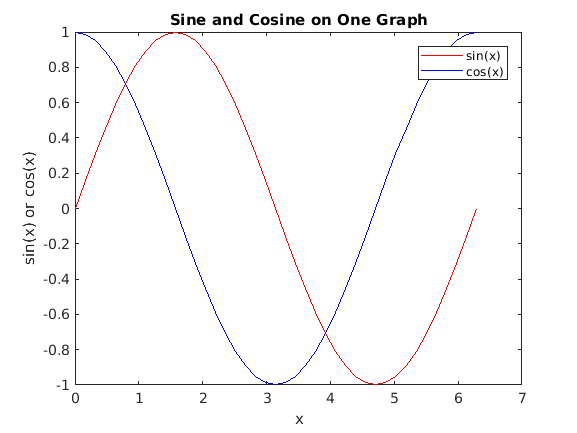

% a shorter way
clf
x = 0: 2*pi/40: 2*pi; 
plot(x, sin(x), 'r-', x, cos(x), 'b-')

legend('sin(x)', 'cos(x)')
xlabel('x')
ylabel('sin(x) or cos(x)')
title('Sine and Cosine on One Graph')

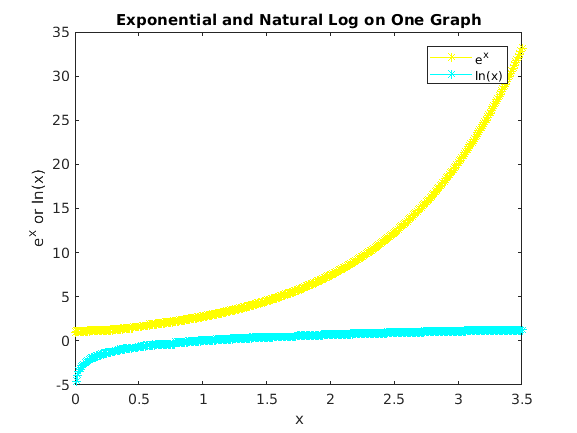

% Plotting Exp and Log(x)
x = 0: 0.01: 3.5; 
plot(x, exp(x), 'y-*', x, log(x), 'c-*')

legend('e^x', 'ln(x)')
xlabel('x')
ylabel('e^x or ln(x)')
title('Exponential and Natural Log on One Graph')